
obj = MainAudio.obj;

t = [406 407]

t =    406   407


fs = obj.fs;
vec = obj.vec(round((1+t(1)*fs):(t(2)*fs)));

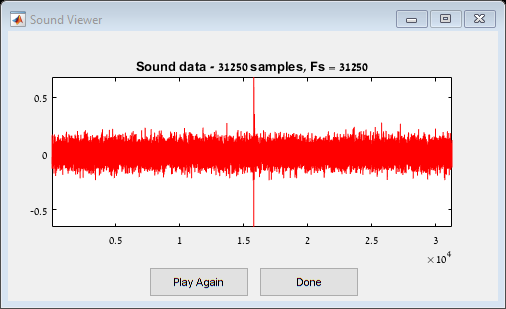

fromFs = 40000;
toFs = 5000;
fsratio = round(fromFs/toFs);

newFs = fs/fsratio;

newVec = downsample(vec,fsratio);
soundview(newVec*20,newFs)